
%  Daniel Kawano, Rose-Hulman Institute of Technology
%  Last modified:  Feb 02, 2016

clear
%close all
%clc

%  Load the symbolic function handles for the state equations in
%  mass-matrix form, M(t,Y)*Y'(t) = F(t,Y):

load t_handle_ODEs

%  Physical parameters:

lambda1 = 0.4;          %  kg-m^2
lambda2 = 0.3;          %  kg-m^2
lambda3 = 0.2;          %  kg-m^2

%  Simulation parameters:

tf = 10;                        %  s
dt = 0.005;                     %  s
tsim = [0 : dt : tf]';          %  s
tol = 1e-6; 

omega10 = 0.5;                  %  rad/s
omega20 = 15;                   %  rad/s
omega30 = 0.5;                  %  rad/s
psi0 = 0;                       %  rad
theta0 = 90*(pi/180);           %  rad
phi0 = 0;                       %  rad

Y0 = [omega10, omega20, omega30, psi0, theta0, phi0]';

%  Plotting parameters:

span = [0.8, 1.2];

%  Convert M(t,Y) and F(t,Y) to purely numeric function handles for
%  numerical integration:

M = @(t, Y) M(t, Y, lambda1, lambda2, lambda3);
F = @(t, Y) F(t, Y, lambda1, lambda2, lambda3);

%  Numerically integrate the state equations:

options = odeset('mass', M, 'abstol', tol, 'reltol', tol);

[t, Y] = ode45(F, tsim, Y0, options);

%  Extract the results:

omega1 = Y(:,1);        %  rad/s
omega2 = Y(:,2);        %  rad/s
omega3 = Y(:,3);        %  rad/s
psi = Y(:,4);           %  rad
theta = Y(:,5);         %  rad
phi = Y(:,6);           %  rad

%to save data
save numericalsoln.mat omega1 omega2 omega3 t

%  Calculate and plot the T-handle's total mechanical energy over time:

E = 1/2*(lambda1*omega1.^2 + lambda2*omega2.^2 + ...        %  J
         lambda3*omega3.^2);

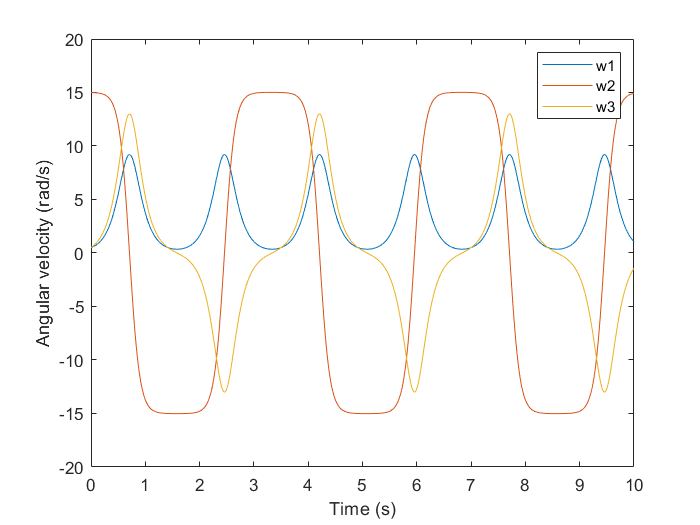

figure
set(gcf, 'color', 'w')
plot(t, omega1, t, omega2, t, omega3)
xlabel('Time (s)')
ylabel('Angular velocity (rad/s)')
legend('w1', 'w2', 'w3')

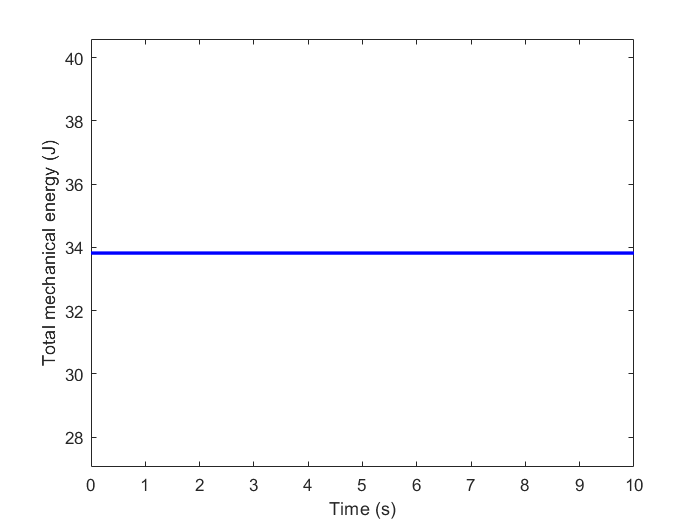


figure
set(gcf, 'color', 'w')
plot(t, E, '-b', 'linewidth', 2)
xlabel('Time (s)')
ylabel('Total mechanical energy (J)')
ylim([min(min(E)*span), max(max(E)*span)])

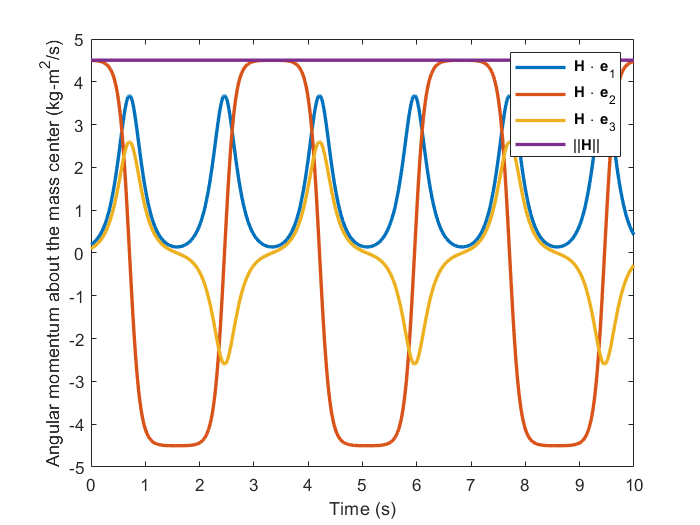


%  Calculate and plot the components of the angular momentum about the mass
%  center and the total angular momentum over time:

H1 = lambda1*omega1;                        %  kg-m^2/s
H2 = lambda2*omega2;                        %  kg-m^2/s
H3 = lambda3*omega3;                        %  kg-m^2/s
H = sqrt(H1.^2 + H2.^2 + H3.^2);            %  kg-m^2/s

figure
set(gcf, 'color', 'w')
plot(t, H1, t, H2, t, H3, t, H, 'linewidth', 2)
xlabel('Time (s)')
ylabel('Angular momentum about the mass center (kg-m^2/s)')
legend(' \bf{H}\rm \cdot \bf{e}\rm_{1}', ...
       ' \bf{H}\rm \cdot \bf{e}\rm_{2}', ...
       ' \bf{H}\rm \cdot \bf{e}\rm_{3}', ...
       ' ||\bf{H}\rm||')

   
%  Animate the motion of the T-handle:

%de_numerical3_model(psi, theta, phi, dt);